clear all;
close all;
clc;
%Torrey Pines buoy correlation
%start time is May 09 2020 05:00:00
startTime = 20200509050000;
%end time is May 15 2020 01:30:00
endTime = 20200515013000;
%load glider data
gliderTable = readtable('metbuoy_26-03.csv');
%get waveglider time and wind vectors for appropriate times
[wgt wgWind10m ~] = gliderTime(gliderTable, startTime, endTime);
%upload san nic band frequency table
freqTable = readtable('Torrey_Pines_May2020.txt');

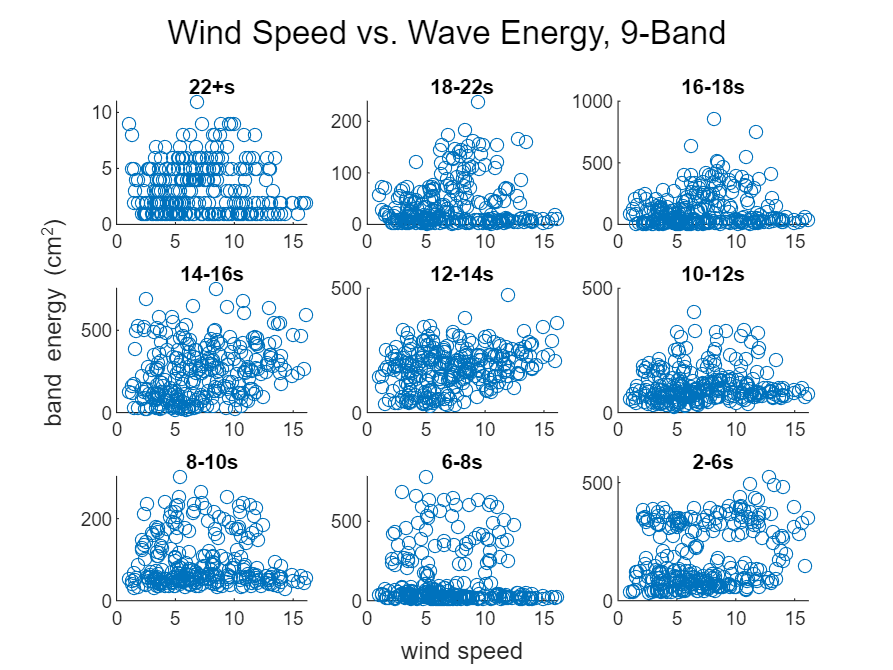

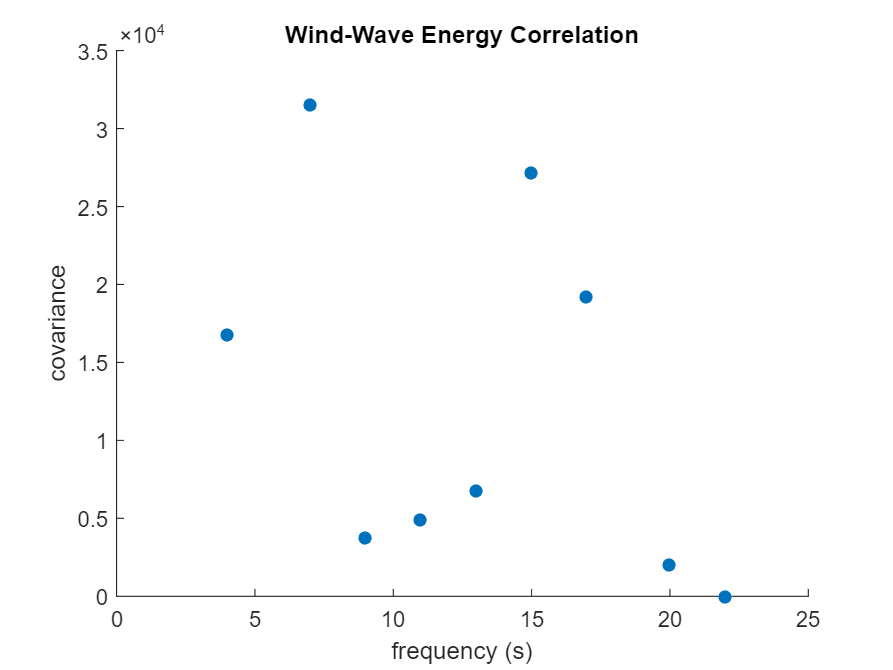

%correlation
windWaveCorr(freqTable, startTime, endTime, wgt, wgWind10m)